# Check for Environmental Collisions with Manipulators

Generate a collision-free trajectory in a constrained workspace.

## Define an environment

You can create a simple environment using collision primitives. For example, suppose the robot is in a workspace where the aim is to move objects from one table to another while avoiding a circular light fixture. These objects can be modeled as two boxes and a sphere. More complex `environments` can be created using [`collisionMesh`](docid:robotics_ref.mw_a620e54b-94a8-41ef-9388-db6daf941221) objects.

% Create two platforms
platform1 = collisionBox(0.5,0.5,0.25);
platform1.Pose = trvec2tform([-0.5 0.4 0.2]);

platform2 = collisionBox(0.5,0.5,0.25);
platform2.Pose = trvec2tform([0.5 0.2 0.2]);

% Add a light fixture, modeled as a sphere
lightFixture = collisionSphere(0.1);
lightFixture.Pose = trvec2tform([.2 0 1]);

% Store in a cell array for collision-checking
worldCollisionArray = {platform1 platform2 lightFixture};

Visualize the environment using a helper function that iterates through the collision array.

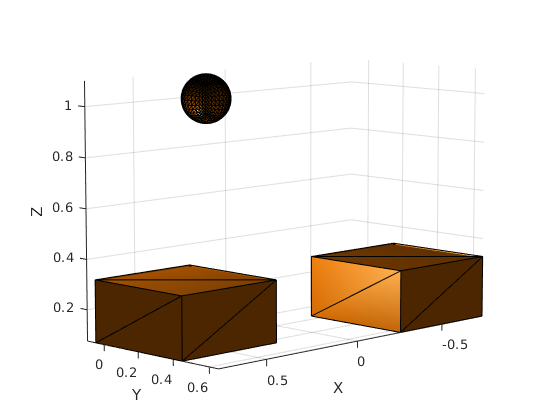

exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);

## Add a manipulator robot

Add a Kinova manipulator to the environment at the origin. Load the provided robot model. Visualize the obstacles and show the robot in the same figure.

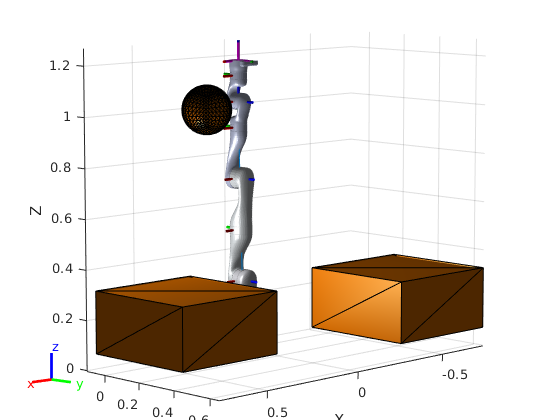

robot = loadrobot("kinovaGen3","DataFormat","column","Gravity",[0 0 -9.81]);
ax = exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);
show(robot,homeConfiguration(robot),"Parent",ax);

## Model the manipulator as an array of collision objects

Create an array of collision objects from the [`rigidBodyTree`](docid:robotics_ref.bvan8uq-1) object. This approach uses an example helper, `exampleHelperManipCollisionsFromVisuals`, that extracts the meshes from the first visual in each [`rigidBody`](docid:robotics_ref.bvam99a-1) object. For an overview of other approaches, refer to [Create Collision Objects for Manipulator Collision Checking](docid:robotics_examples.mw_ac1fd439-ee7d-4bc8-8f58-8d6754597669).

% Generate an array of collision objects from the visuals of the associated tree
collisionArray = exampleHelperManipCollisionsFromVisuals(robot);

## Generate a trajectory and check for collisions

Define a start and end pose as position and orientation. Use [`inverseKinematics`](docid:robotics_ref.bvdhj7x-1) to solve for the joint positions based on the desired poses. Inspect manually to verify that the configurations are valid.

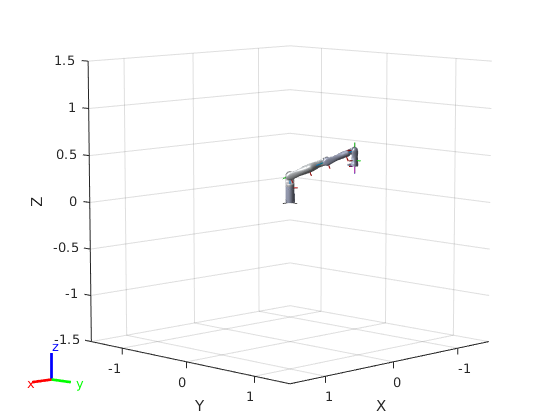

startPose = trvec2tform([-0.5,0.5,0.4])*axang2tform([1 0 0 pi]);
endPose = trvec2tform([0.5,0.2,0.4])*axang2tform([1 0 0 pi]);

% Use a fixed random seed to ensure repeatable results
rng(0);
ik = inverseKinematics("RigidBodyTree",robot);
weights = ones(1,6);
startConfig = ik("EndEffector_Link",startPose,weights,robot.homeConfiguration);
endConfig = ik("EndEffector_Link",endPose,weights,robot.homeConfiguration);

% Show initial and final positions
show(robot,startConfig);

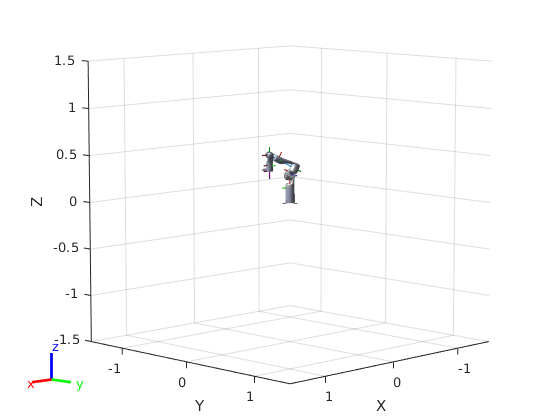

show(robot,endConfig);

Use a trapezoidal velocity profile to generate a smooth trajectory from the home position to the start position, and then to the end position. Use collision checking to see whether this results in any collisions.

q = trapveltraj([homeConfiguration(robot),startConfig,endConfig],200,"EndTime",2);

%Initialize outputs
isCollision = false(length(q),1); % Check whether each pose is in collision
selfCollisionPairIdx = cell(length(q),1); % Provide the bodies that are in collision
worldCollisionPairIdx = cell(length(q),1); % Provide the bodies that are in collision

for i = 1:length(q)
    [isCollision(i),selfCollisionPairIdx{i},worldCollisionPairIdx{i}] = exampleHelperManipCheckCollisions(robot,collisionArray,worldCollisionArray,q(:,i),false);
end
isTrajectoryInCollision = any(isCollision)

isTrajectoryInCollision = logical
   1


## Inspect the Problem Cases

By inspecting the collisions, there are 2 collisions occurring. Visualize these configurations to investigate further.

problemIdx1 = find(isCollision,1);
problemIdx2 = find(isCollision,1,"last");

% Identify the problem rigid bodies
problemBodies1 = [selfCollisionPairIdx{problemIdx1} worldCollisionPairIdx{problemIdx1}*[1 0]'];
problemBodies2 = [selfCollisionPairIdx{problemIdx2} worldCollisionPairIdx{problemIdx2}*[1 0]'];

% Visualize the environment
ax = exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);

% Add the robots & highlight the problem bodies
show(robot,q(:,problemIdx1),"Parent",ax,"PreservePlot",false);
exampleHelperHighlightCollisionBodies(robot,problemBodies1,ax);
show(robot,q(:,problemIdx2),"Parent"',ax);
exampleHelperHighlightCollisionBodies(robot,problemBodies2,ax);


## Generate a Collision-Free Trajectory using Intermediate Waypoints

To avoid these collisions, add intermediate waypoints to ensure the robot navigates around the obstacle.

intermediatePose1 = trvec2tform([-.3 -.2 .6])*axang2tform([0 1 0 -pi/4]); % Out and around the sphere
intermediatePose2 = trvec2tform([0.2,0.2,0.6])*axang2tform([1 0 0 pi]); % Come in from above

intermediateConfig1 = ik("EndEffector_Link",intermediatePose1,weights,q(:,problemIdx1));
intermediateConfig2 = ik("EndEffector_Link",intermediatePose2,weights,q(:,problemIdx2));

% Show the new intermediate poses
ax = exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);
show(robot,intermediateConfig1,"Parent",ax,"PreservePlot",false);
show(robot,intermediateConfig2,"Parent",ax);

Generate a new trajectory.

[q,qd,qdd,t] = trapveltraj([homeConfiguration(robot),intermediateConfig1,startConfig,intermediateConfig2,endConfig],200,"EndTime",2);

Verify that it is collision-free.

%Initialize outputs
isCollision = false(length(q),1); % Check whether each pose is in collision
collisionPairIdx = cell(length(q),1); % Provide the bodies that are in collision
for i = 1:length(q)
    [isCollision(i),collisionPairIdx{i}] = exampleHelperManipCheckCollisions(robot,collisionArray,worldCollisionArray,q(:,i),false);
end
isTrajectoryInCollision = any(isCollision)

## Visualize the Generated Trajectory

Animate the result.

% Plot the environment
ax2 = exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);

% Visualize the robot in its home configuration
show(robot,startConfig,"Parent",ax2);

% Update the axis size
axis equal

% Loop through the other positions
for i = 1:length(q)
    show(robot,q(:,i),"Parent",ax2,"PreservePlot",false);
    
    % Update the figure    
    drawnow
end

Plot the joint positions over time.

figure
plot(t,q)
xlabel("Time")
ylabel("Joint Position")

*Copyright 2019 The MathWorks, Inc.*